## `Generating Matrix`

`1. Load and verify dataset`

% Load the dataset
data = readtable('cleaned_bangalore_zomato_data.csv');

% Display the column names for verification
disp(data.Properties.VariableNames);

  Columns 1 through 6

    {'Restaurant_lati…'}    {'Restaurant_long…'}    {'Delivery_locati…'}    {'Delivery_locati…'}    {'multiple_delive…'}    {'Time_taken_min'}

  Columns 7 through 13

    {'Time_Difference'}    {'Order_Hour'}    {'Distance'}    {'Weather_conditi…'}    {'Weather_conditi…'}    {'Weather_conditi…'}    {'Weather_conditi…'}

  Columns 14 through 19

    {'Weather_conditi…'}    {'Weather_conditi…'}    {'Road_traffic_de…'}    {'Road_traffic_de…'}    {'Road_traffic_de…'}    {'Road_traffic_de…'}

  Columns 20 through 25

    {'Vehicle_conditi…'}    {'Vehicle_conditi…'}    {'Vehicle_conditi…'}    {'Type_of_order_B…'}    {'Type_of_order_D…'}    {'Type_of_order_M…'}

  Columns 26 through 29

    {'Type_of_order_S…'}    {'Type_of_vehicle…'}    {'Type_of_vehicle…'}    {'Type_of_vehicle…'}



`2.  Extract Necessary Columns and Combine Unique Locations`

% Extract the necessary columns
restaurant_latitudes = data.Restaurant_latitude;
restaurant_longitudes = data.Restaurant_longitude;
delivery_latitudes = data.Delivery_location_latitude;
delivery_longitudes = data.Delivery_location_longitude;
time_taken = data.Time_taken_min;

% Combine restaurant and delivery locations into one list of unique locations
locations = unique([restaurant_latitudes, restaurant_longitudes; delivery_latitudes, delivery_longitudes], 'rows');

% Number of unique locations
numLocations = size(locations, 1);

`3. Preallocate Matrices and Initialize Constants`

% Preallocate the distance and time matrices
distanceMatrix = zeros(numLocations);
timeMatrix = zeros(numLocations);

% Haversine formula to calculate the great-circle distance between two points
earthRadius = 6371; % Earth's radius in kilometers

`4. Calculate Distance and Time Matrices with Adjustments`

% Loop through each pair of unique locations
for i = 1:numLocations
    for j = 1:numLocations
        if i ~= j
            % Coordinates of the first location
            lat1 = locations(i, 1);
            lon1 = locations(i, 2);
            
            % Coordinates of the second location
            lat2 = locations(j, 1);
            lon2 = locations(j, 2);
            
            % Calculate the differences in latitude and longitude
            dLat = deg2rad(lat2 - lat1);
            dLon = deg2rad(lon2 - lon1);
            
            % Apply the Haversine formula
            a = sin(dLat/2) * sin(dLat/2) + cos(deg2rad(lat1)) * cos(deg2rad(lat2)) * sin(dLon/2) * sin(dLon/2);
            c = 2 * atan2(sqrt(a), sqrt(1-a));
            distance = earthRadius * c;
            
            % Initialize the condition factor to 1
            condition_factor = 1;
            
            % Find the index of the delivery location corresponding to the current location
            delivery_index = find(ismember([delivery_latitudes, delivery_longitudes], locations(i, :), 'rows'), 1);
            
            if ~isempty(delivery_index)
                % Adjusting the condition factor based on weather conditions
                if data.Weather_conditions_Cloudy(delivery_index) == 1
                    condition_factor = condition_factor * 1.1;
                end
                if data.Weather_conditions_Fog(delivery_index) == 1
                    condition_factor = condition_factor * 1.3;
                end
                if data.Weather_conditions_Sandstorms(delivery_index) == 1
                    condition_factor = condition_factor * 1.4;
                end
                if data.Weather_conditions_Stormy(delivery_index) == 1
                    condition_factor = condition_factor * 1.5;
                end
                if data.Weather_conditions_Sunny(delivery_index) == 1
                    condition_factor = condition_factor * 0.9;
                end
                if data.Weather_conditions_Windy(delivery_index) == 1
                    condition_factor = condition_factor * 1.2;
                end
                
                % Adjust the condition factor based on traffic conditions
                if data.Road_traffic_density_Jam(delivery_index) == 1
                    condition_factor = condition_factor * 2.0;
                end
                if data.Road_traffic_density_High(delivery_index) == 1
                    condition_factor = condition_factor * 1.3;
                end
                if data.Road_traffic_density_Low(delivery_index) == 1
                    condition_factor = condition_factor * 0.8;
                end
                if data.Road_traffic_density_Medium(delivery_index) == 1
                    condition_factor = condition_factor * 1.1;
                end
                
                % Calculate the adjusted distance and time
                adjusted_distance = distance * condition_factor;
                distanceMatrix(i, j) = adjusted_distance;
                
                % Adjust time using the provided time_taken column
                adjusted_time = time_taken(delivery_index) * condition_factor;
                timeMatrix(i, j) = adjusted_time;
            else
                % If no corresponding delivery location is found, assign Inf to both matrices
                distanceMatrix(i, j) = Inf;
                timeMatrix(i, j) = Inf;
            end
        else
            % If the locations are the same, assign Inf to both matrices
            distanceMatrix(i, j) = Inf;
            timeMatrix(i, j) = Inf;
        end
    end
end

`5. Save Matrices and Visualize Paths`

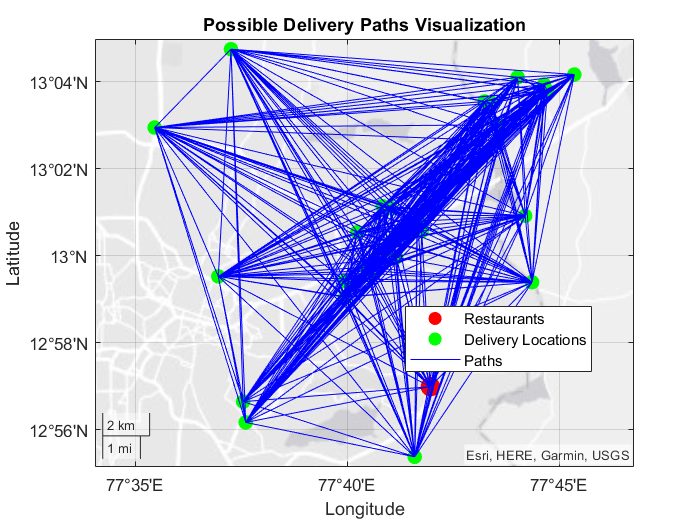

% Save the distance and time matrices to CSV files
writematrix(distanceMatrix, 'distance_matrix_adjusted.csv');
writematrix(timeMatrix, 'time_matrix_adjusted.csv');

% Visualize the paths using geoplot
figure;
geoaxes; % Create geoaxes
geoplot(restaurant_latitudes, restaurant_longitudes, 'r.', 'MarkerSize', 40); % Plot restaurant locations in red
hold on;
geoplot(delivery_latitudes, delivery_longitudes, 'g.', 'MarkerSize', 30); % Plot delivery locations in green

% Plot paths between locations
for i = 1:numLocations
    for j = 1:numLocations
        if distanceMatrix(i, j) < Inf % Only plot if there is a valid distance
            geoplot([locations(i, 1), locations(j, 1)], [locations(i, 2), locations(j, 2)], 'b-');
        end
    end
end
hold off;

% Add titles and labels
title('Possible Delivery Paths Visualization');

% Add text labels for each point
for i = 1:numel(restaurant_latitudes)
    text(restaurant_longitudes(i), restaurant_latitudes(i), sprintf('R%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'red');
end

for i = 1:numel(delivery_latitudes)
    text(delivery_longitudes(i), delivery_latitudes(i), sprintf('D%d', i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right', 'Color', 'green');
end

% Add a legend and move it to the best location
legend({'Restaurants', 'Delivery Locations', 'Paths'}, 'Location', 'best');